#     MiniProject 1: Decimation and Interpolation of Discrete-time Signals

# DUE: FRIDAY - 09/24/2021, 11:59 pm via BLACKBOARD

# TOTAL POINTS - 20

# READ FIRST: 

## Objective: 

In this miniproject, you will apply your basic knowledge of MATLAB scripting and create a **tutorial **using MATLAB Livescript on fundamental signal operation studied in **Chapter - 2 and 3**. You should treat this livescript file as a self contained tutorial that **correctly **demonstrates the mathematical concepts learnt in class. **You will be graded based on your creativity, originality, presentation along with the correctness of your code and the plots that will be generated in each of the sections below. **

## **Follow these steps before answering the questions below:**

**Step 1:** Rename the .mlx file as "YourFirstName_LastNameInitial_MP1.mlx". **You will submit this file for grading along with any addtional files requested in the assignments below. **

**Step 2: DO NOT MODIFY OR ALTER THE SECTIONS OR THE ORDER IN THE TEMPLATE. ONLY MAKE CHANGES TO THE ASSIGNED AREAS FOR CODE AND TEXTS.**

**Step 3:** Review **sections 2.5 and 3.5** and work on example problems. Put extra emphasis on **Time Compression **and **Time Expansion** in section 3.5. This is what you will have to implement in this miniproject. 

**Step 4:** Download the MATLAB examples for **Chapter 2 and 3** from the student companion website from the publisher that has been shared with you earlier. Speicfically copy the code corresponding to **Examples 2.2 and 3.1 **in the text**. **Study the details of these two example scripts in detail and relate your mathematical understanding with the implementation in the code. Undertsand the difference in the two implementations and why it is different for continous-time and discrete-time signals. Copying those into a seprate .mlx file will allow you to explore the subtleties of the script. Pay extra attention in the time compression and expansion part of the code in Example 3.1. 

**Step 5: Grading: **There are 4 sections in the project, each worth a maximum of **4pts**. Your work will be graded on correctness of the implementation and your ability to explain why do you think that your code is correct. The remaining **4pts** will be for overall creative thinking of the tutorial, your ability to clearly present the underlying concepts, aesthetics of the plots, interactive elements, comments and ease of replication of the resuts, etc. You are free to add your own explanatory texts and/or references to the textbook if that helps you make a better presentation. Imagine yourself as a teacher, explaining this idea to high school students using this livescript, assuming they know what discrete-time signals are.

## ***Submitted By: Student Name***

## *Part One: Your voice as a discrete-time signal*

#### ***OBJECTIVE: This part tests your ability to navigate the MATLAB documentation to implement something new and teach yourself how different parameters impact the properties of a discrete-time signal. ***

#### **NOTE: All the information you will need to complete this part is given in the MATLAB documentation. I recommend typing "record audio" in the doc search bar on top right corner of the MATLAB window.**

**TASK 1.1:** Write a code to capture audio into a file and play it back.. Just say the **initials of your name;** Two letters with a pause in between.

% Insert your code here!
% Record
clear all 
myVoice = audiorecorder;
myVoice.StartFcn = 'disp(''Start speaking.'')';
myVoice.StopFcn = 'disp(''End of recording.'')';

record(myVoice, 5);

Start speaking.


% Playback

pause(4); 
play(myVoice);

% Save the audio samples as a .mat file for submission so that I can listen
% to it as well. 

%save("task1.mat","myVoice",'-mat');

% Provide the code to playback the audio from your .mat file.

%load taskl.mat % Loads Mat File
%play(myVoice); %Plays audio inside Mat File

**TASK 1.2:** Plot the waveform of the audio file **using two different types of plots**, for example, line, stem, bar, etc. Use **subplot()** to plot two plots in one figure window. Make sure that you include plot title, axis labels and any other annotations you may like.

% Include your code he  re and show plot on the right panel. You can also try to make it interactive! 
clear all

End of recording.


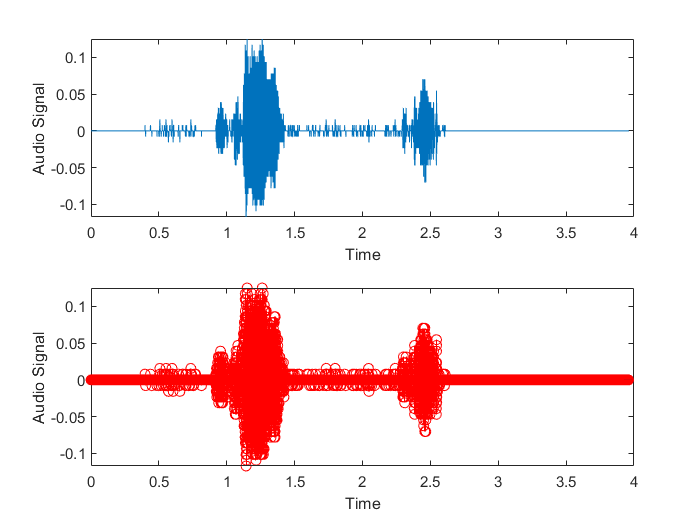

load task1.mat
fs= 8140; %Sampling Rate of task
y = getaudiodata(myVoice); %Total sampling

%Conversion From .mat to .wav --- Extra Code--
%audiowrite('audio1.wav',y,Fs); %converts Mat to Wav
%[y,fs] = audioread('audio1.wav'); % Reads wav file

%first plot

subplot(2,1,1);
plot(y); 
title('Audio Sample')
xlabel('Number Of Samples');
ylabel('Audio Signal');

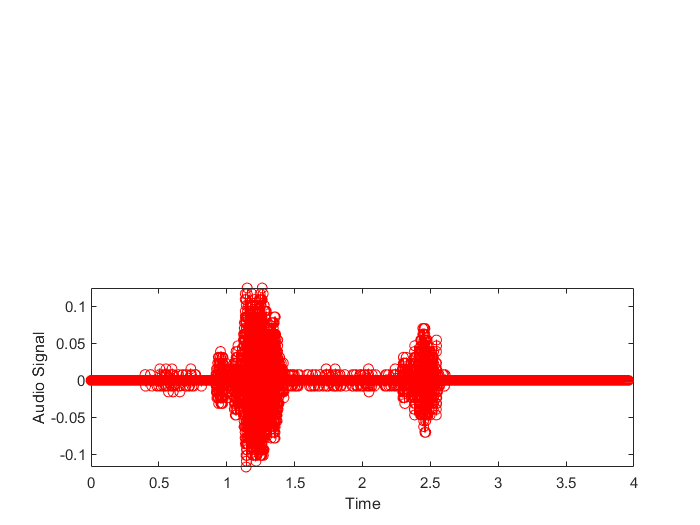



%Second plot
subplot(2,1,2);
stem(y,"Color",'R'); 
xlabel('Number Of Samples','filled');
ylabel('Audio Signal');

title('Audio Sample-Stem')
figure

Unrecognized function or variable 'figure7220'.

## *Part Two: Understand the parameters of your recording*

#### ***OBJECTIVE: This part tests your understanding on the role of sampling frequency and sampling resolution on the quality of the audio recording. ***

**TASK 2.1:** Edit your code in **Part 1** and include **sliders **to control the **number of bits per sample and the sampling frequency parameters** used to process your file. Then, update your plot and playback with the altered signals and **discuss how the plot changes**. You may comment on the number of samples, their amplitudes, quality of the audio and anything else you observe. 

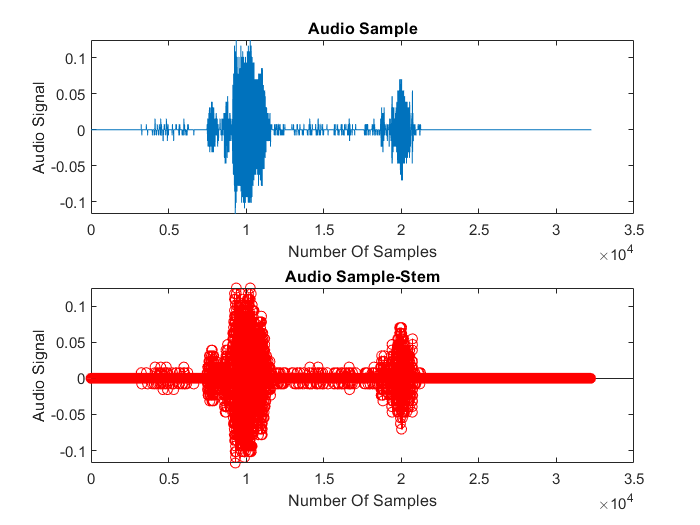

% Insert your code here!
% Update plot above or create new plot
% Include your code he  re and show plot on the right panel. You can also try to make it interactive! 
clear all

load task1.mat
y = getaudiodata(myVoice); %Total sampling

fs= 8860;%Sampling Frequency
bits = 64;%Number of Bits Per sample

audiowrite("task1.wav",y,fs,'BitsPerSample',  bits); %Creates Wav file with custom fs and Bits

[y,fs] = audioread('task1.wav'); %Read data back into Matlab 
%first plot
subplot(2,1,1);
plot(y); 
xlabel('Number Of Samples');
ylabel('Audio Signal');
title('Audio Sample')
%Second plot
subplot(2,1,2);
stem(y,"Color",'R'); 
xlabel('Number Of Samples');
ylabel('Audio Signal');
title('Audio Sample-Stem')

figure
% Playback altered audio'
sound(y,fs);
pause(5);


**TASK 2.2:** What can you conclude or infer about the role of **sampling frequency** and **number of bits per sample** in storing or processing digital signals? Explain in words the cause of the changes that occur in the plots and what does it mean for the quality of the audio.

% Insert your answer here! Although this not a code but use this space to write your answer as a MATLAB comment
When I increased the sampling frequency the pitch of the audio increased and the plot widened. When I increased the number of bits per sample

Unrecognized function or variable 'When'.

the audio got clearer and the plot did not change significantly.




## Part Three: Shift and Scale your recording. 

#### *OBJECTIVE:  To understand and simulate basic signal manipulation methods like shift and scale*

**TASK 3.1:** Delay and scale a portion of your signal and show it via interactive plots.

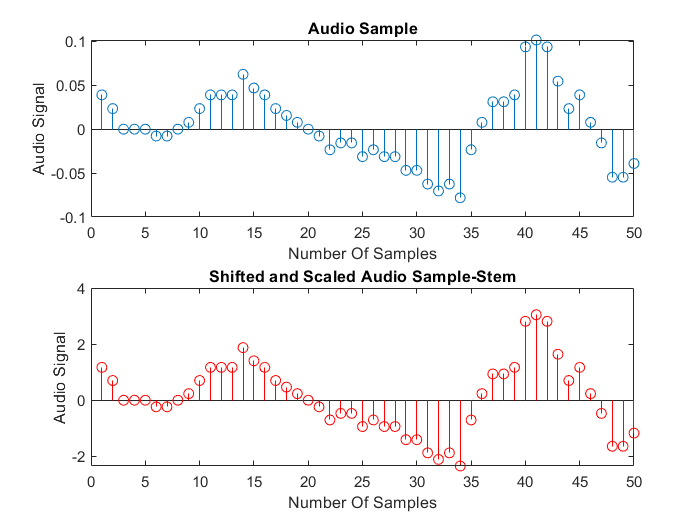

% Step 1: Extract few samples (N < 50) from any portion of your recording, preferabley where the audio signal is. 
% You should be able to identify where the audio samples are from your implementation and plots in Parts 1 and 2.

% Code to cut out a section of the recording
clear all

load task1.mat
y = getaudiodata(myVoice); %Total sampling
N = [.95E4:.9549E4];
fs= 8410;%Sampling Frequency
bits = 16;%Number of Bits Per sample
A = 30;
to =0;



% STEP 2: Code for shift and scale of the form g2(t) = Ag1(a(t-t_0)). Where g1(t) is the signal you created in the previous lines. Plot g2(t) and make it as
% interactive as possible, with livescript controls like sliders, textbox, etc. Label and annotate plots properly

audiowrite("task1.wav",y,fs,'BitsPerSample', bits); %Creates Wav file with custom fs and Bits
info = audioinfo('task1.wav');%Checks for Files info, contains Fs and BitsPerSample
[y,fs] = audioread('task1.wav'); %Read data back into Matlab 
%first plot
g0 = y(N);
g1 = A*y(N-to);

subplot(2,1,1);
stem(g0); 
xlabel('Number Of Samples');
ylabel('Audio Signal');
title('Audio Sample')
%Second plot
subplot(2,1,2);
stem(g1,"Color",'R'); 
xlabel('Number Of Samples');
ylabel('Audio Signal');
title('Shifted and Scaled Audio Sample-Stem')

figure
% Playback altered audio'
sound(y,fs);
pause(5);






**TASK 3.2:** Differentiate and intergrate a discrete-time signal without using standard MATLAB functions. Which of the aforementioned mathematical operations made the signal more noisy? In other words, how can you tell if your impementation is indeed correct. Explain briefly as a MATLAB comment in the second code box below. 

**NOTE: As we learnt in class and also from section 3.6 in the textbook, differetiation and integration of discrete-time functions is called Differencing and Accumulation. Review the material in that section and write a code for your own implementation of these two operations and plot your results. You cannot use the diff() and the cumsum() function in MATLAB. **

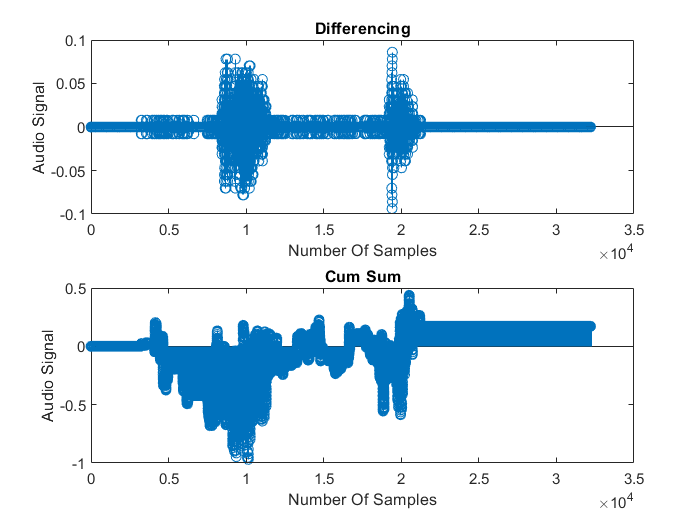

% Insert your code here to Differencing and Accumulation and plot on the right! 
load task1.mat
y = getaudiodata(myVoice);
%Differencing
for i= 1:length(y)-1
    x(i) = y(i+1)-y(i);
end
subplot(2,1,1);
stem(x);
xlabel('Number Of Samples');
ylabel('Audio Signal');
title('Differencing');
%Accumulation
z(1) = y(1);
for i = 2:length(y)
   z(i) = z(i-1)+ y(i);%recursive
end
subplot(2,1,2);
stem(z);
title('Cum Sum');
xlabel('Number Of Samples');
ylabel('Audio Signal');

figure

% Your response on how to assess the correctness of you implementation
%How to check
diff(y);
cumsum(y);

## Part Four: Energy of the signal

#### *OBJECTIVE: To understand how the energy of a signal changes when multiplied by another signal. *

**TASK 4.1:** Calculate the energy of the signal g1(t) and g2(t). You can also add interactive elements here for different shift and scale parameters. 

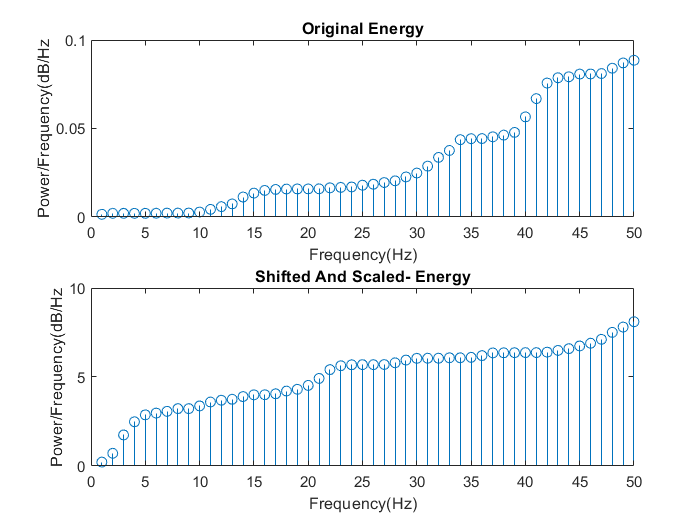

% Include your code here and plot on the right panel!
clear all
load task1.mat

y = getaudiodata(myVoice);
N = [0.95E4:0.9549E4];%50 Samples
fs= 8410;%Sampling Frequency
bits = 64;%Number of Bits Per sample
A = 10;
to =80;
audiowrite("task1.wav",y,fs,'BitsPerSample', bits); %Creates Wav file with custom fs and Bits
info = audioinfo('task1.wav');%Checks for Files info, contains Fs and BitsPerSample
[y,fs] = audioread('task1.wav'); %Read data back into Matlab 

g0 = y(N);%Original Energy
g1 = A*y(N-to);%Transformed Energy
g0 = g0.^2;
g1 = g1.^2;
subplot(2,1,1);
stem(cumsum(g0));%Plot Cumulative Sum
title('Original Energy');
xlabel('Frequency(Hz)');
ylabel('Power/Frequency(dB/Hz');

subplot(2,1,2);
stem(cumsum(g1));
title('Shifted And Scaled- Energy');
xlabel('Frequency(Hz)');
ylabel('Power/Frequency(dB/Hz)');

figure

**TASK 4.2:** Show an example code to demonstrae exponential decay of the amplitude of your orginal recording in Part 1 and plot and replay the audio. The net effect should be an audio whose volume decreases slowly according to the time constant of your chosen exponential . 

% Include your code here!
% Create exponential signal and multiply with original audio
load task1.mat
y = getaudiodata(myVoice);
tc = -1

tc = -1

fs = 8000

fs = 8000

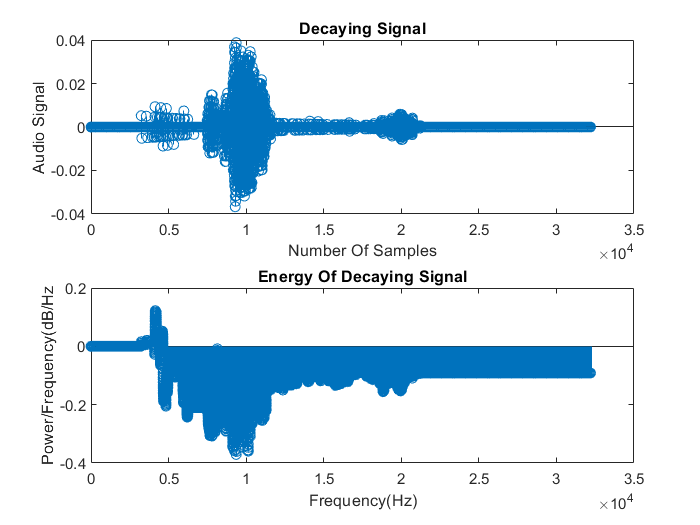

length = size(y,1);
t =(0:length-1)/fs;
exponent = exp(tc*t);%-1 is Time constant
signal = y.* exponent.'; %Transpose signal
% Playback and plot the.' decaying signal
subplot(2,1,1);
stem(signal);
title('Decaying Signal');
xlabel('Number Of Samples');
ylabel('Audio Signal');
%Energy
subplot(2,1,2);
stem(cumsum(signal));
title('Energy Of Decaying Signal');
xlabel('Frequency(Hz)');
ylabel('Power/Frequency(dB/Hz)');

figure
%Original Sound
sound(y,fs);
pause(5);
%Decaying Sound
sound(signal,fs);
